% clear
% mu = 9.9

mu = 9.9000

% sigma = 0.05

sigma = 0.0500

% 
% x = linspace(7,12,100)

x =     7.0000    7.0505    7.1010    7.1515    7.2020    7.2525    7.3030    7.3535    7.4040    7.4545    7.5051    7.5556    7.6061    7.6566    7.7071    7.7576    7.8081    7.8586    7.9091    7.9596    8.0101    8.0606    8.1111    8.1616    8.2121    8.2626    8.3131    8.3636    8.4141    8.4646    8.5152    8.5657    8.6162    8.6667    8.7172    8.7677    8.8182    8.8687    8.9192    8.9697    9.0202    9.0707    9.1212    9.1717    9.2222    9.2727    9.3232    9.3737    9.4242    9.4747


% y = normpdf(x,mu,sigma)

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


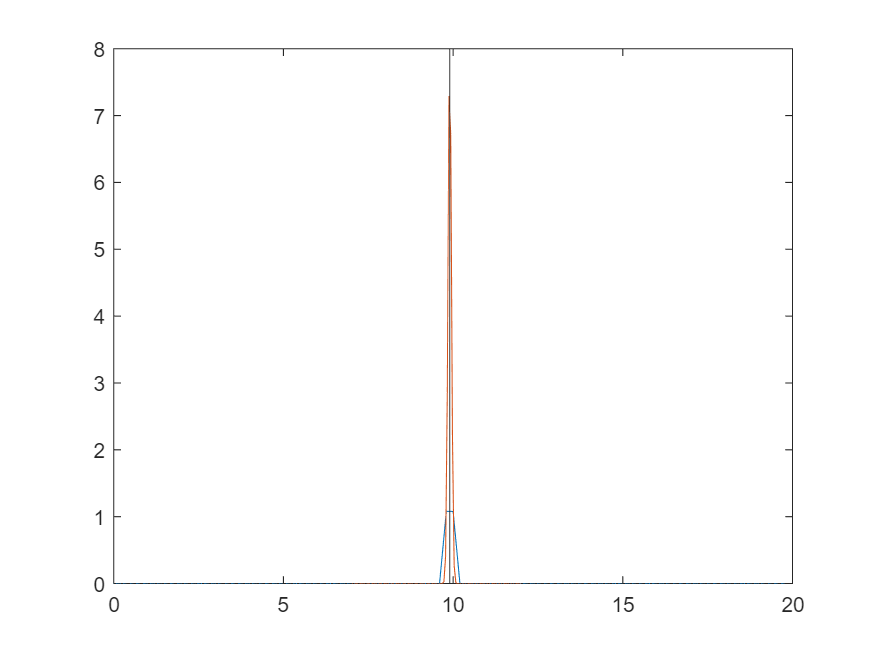

% 
% plot(x,y)
% grid('minor')
% hold on
% xline(mu)

## Opgave 4.22

Et termometer skal kalibreres internt i virksomheden med en usikkerhed på 0,5 °C. Dit kvalitetssystem kræver at du mindst skal have en TUR (Test Uncertainty Ratio) på 3

### A.

Hvilken usikkerhed skal din (interne) referencenormal være?

u_DUT = 0.5; % ønskede usikkerhed på måleren
TUR = 3; % (Test Uncertainty Ratio) 

u_REF = u_DUT/TUR % ønskede usikkerheder på kalibreringsudstyrret

u_REF = 0.1667

Ved kalibrering af referencenormalen er det også et krav at den skal kalibreres i et eksternt kalibreringslaboratorie mod en reference som også skal opfylde at TUR’en er 3

### B.

Hvilken usikkerhed skal det eksterne kalibreringslaboratories reference have?

u_REF_eks = u_REF/TUR

u_REF_eks = 0.0556

### C.

I praksis er den primære realisering af temperatur (0. niveau) forbundet med en usikkerhed på 0.001 °C.

Hvis TUR’en mellem alle kalibreringsniveauer er 3, hvilket niveau skal du så vælge når dit termometer har en usikkerhed på 0,5 °C?

u_REF = 0.001;

niveau = 1:10

niveau =      1     2     3     4     5     6     7     8     9    10



for i = niveau
    u_REF = u_REF*TUR;
    u_REFs(i) = u_REF; 
end

disp(table(niveau',u_REFs'))

    Var1     Var2 
    ____    ______

      1      0.003
      2      0.009
      3      0.027
      4      0.081
      5      0.243
      6      0.729
      7      2.187
      8      6.561
      9     19.683
     10     59.049



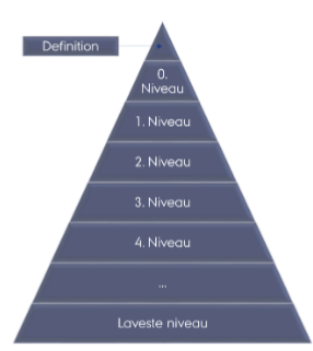

### D.

Beregn hvor meget et referenceinstruments usikkerhed betyder når

a. TUR=3

TUR = 3 % (Test Uncertainty Ratio) 

TUR = 3

n = 4 % niveau

n = 4

start = 0.001 % start niveau usikkerhede

start = 1.0000e-03

u_DUT = TUR^n * start

u_DUT = 0.0810

% u_DUT = 1.054    
u_REF = TUR^3 * start

u_REF = 0.0270

% u_REF = u_DUT / TUR
U_e = sqrt((1*u_DUT)^2 + (-1*u_REF)^2)

U_e = 0.0854

b. TUR=2

TUR = 2 % (Test Uncertainty Ratio) 

TUR = 2

u_DUT = TUR^n * start

u_DUT = 0.0160

c. TUR=1

TUR = 1 % (Test Uncertainty Ratio) 

TUR = 1

u_DUT = TUR^n * start

u_DUT = 1.0000e-03

Hint: Lad 𝑈𝑟𝑒𝑓betegne referencens usikkerhed. Da vil 𝑈𝑑𝑢𝑡=𝑇𝑈𝑅∗𝑈𝑟𝑒𝑓.

### E.

Beskriv hvilken operationel forskel der er mellem et kalibreringshieraki der har mange (f.eks. 6) og få (f.eks. 2) niveauer. Er der økonomisk forskel?

størrer præcision, bliver dyrer, tager mere tid.

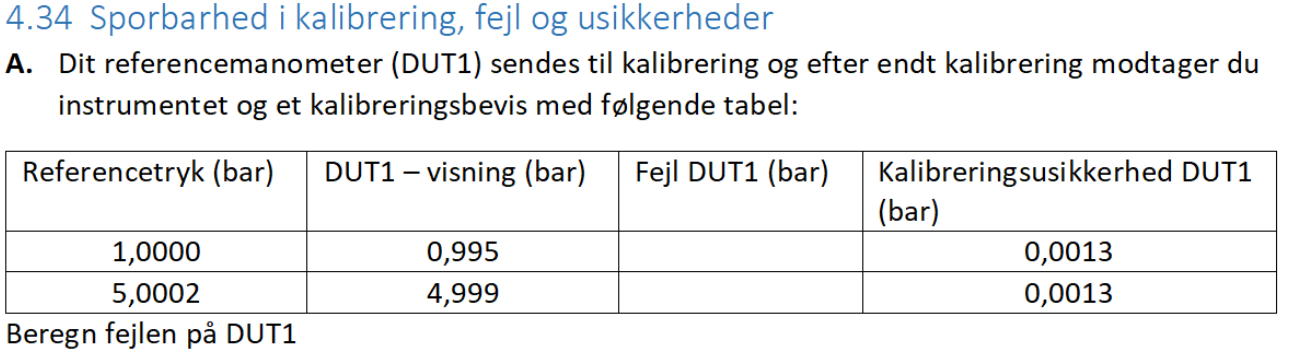

e_DUT1 = 0.995 - 1

e_DUT1 = -0.0050

4.999 - 5.0002 

ans = -0.0012

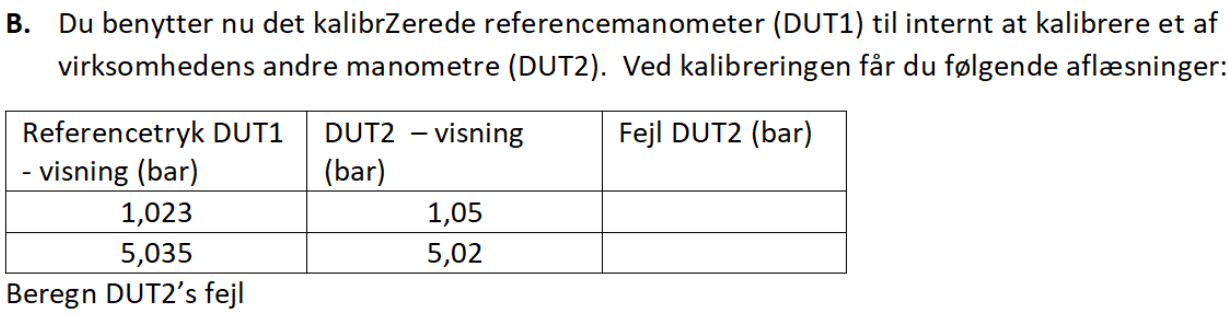

1.05 - 1.023

ans = 0.0270

5.02 - 5.035

ans = -0.0150

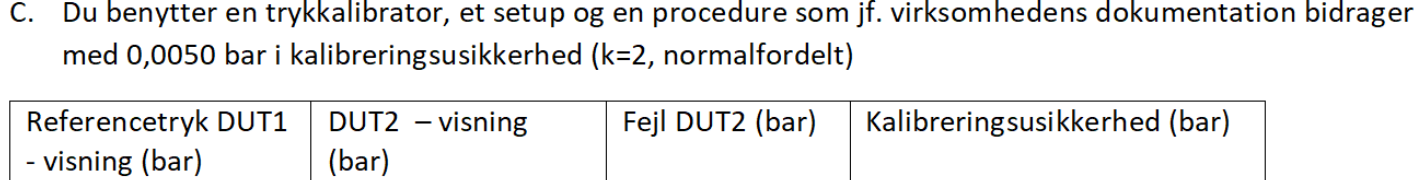

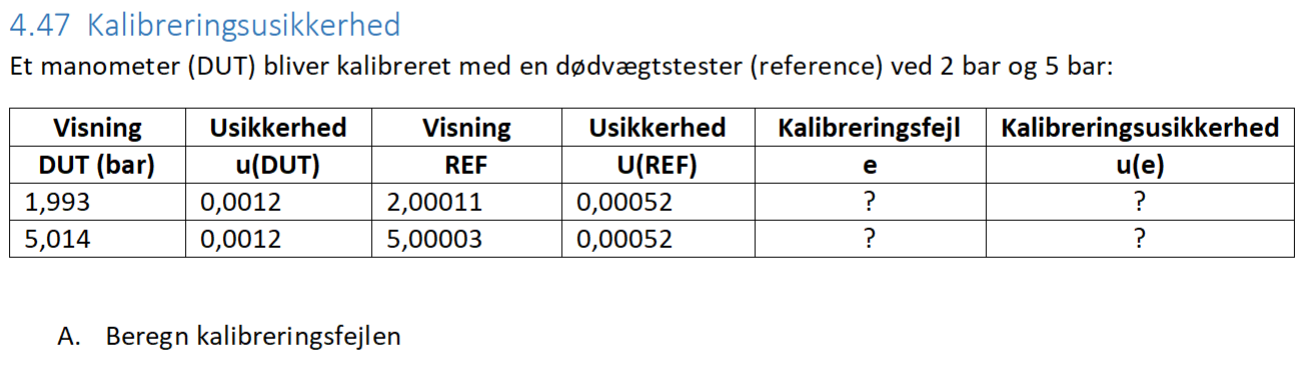

clear
DUTs = [1.993 5.014];
REFs = [2.00011 5.00003];

for i = 1:length(DUTs)
    e(i) = REFs(i) - DUTs(i);
end

e

e =     0.0071   -0.0140


Tilbage i processen indikerer manometeret 3,5123 bar

### B.

Beregn trykket korrigeret for den kendte kalibreringsfejl

a = (e(2) - e(1)) / (DUTs(2) - DUTs(1))

a = -0.0070

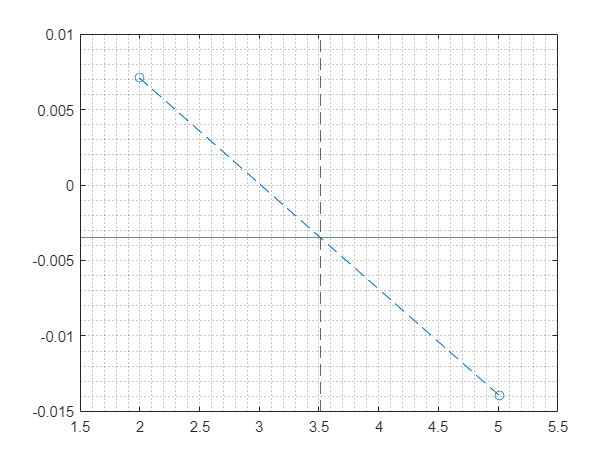

plot([DUTs(1) DUTs(2)], [e(1)  e(2)], 'o--')
xline(3.5123,'--')
grid('minor')
yline(-0.0035, 'r')

Vi aflæser en fejlen på -0,0035

DUT_3 = 3.5123 - 0.0035

DUT_3 = 3.5088

vi får således målingen på 3,5088

% u_DUTs = [0.0012 0.0012];
% U_REFs = [0.00052 0.00052];
% 
% for i = 1:length(DUTs)
%     E(i) = e(i) / sqrt(U_REFs(i)^2 + u_DUTs(i)^2);
% end
% E

Hint: Antag at termometerets fejl er lineært proportional med dets visnin

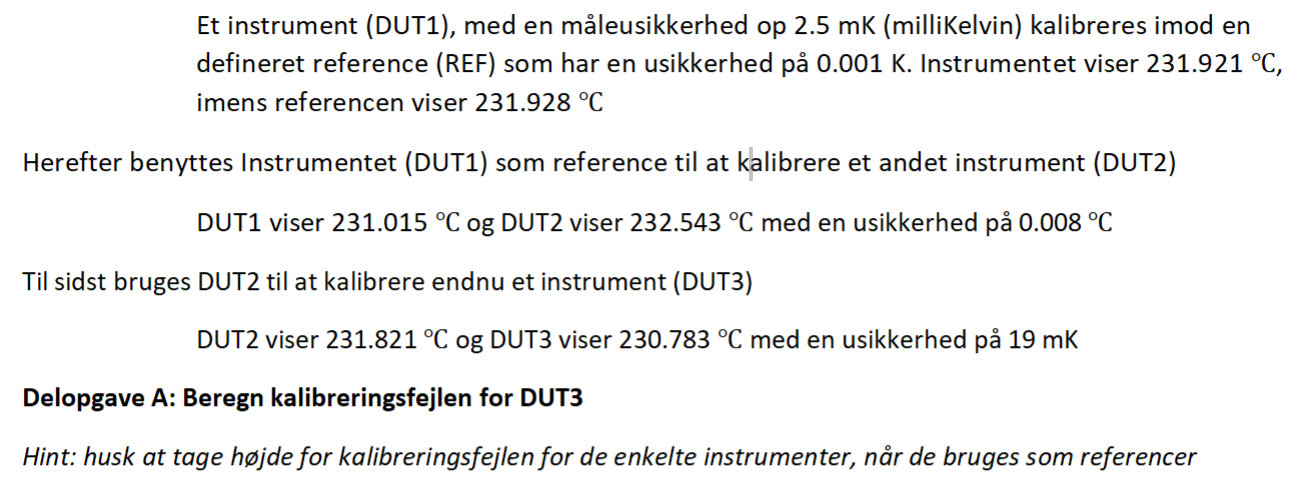

% DUTs = []
REF1 = 231.928;
DUT1 = 231.921;
e = REF1 - DUT1

e = 0.0070

REF2 = DUT1 + e

REF2 = 231.9280


DUTs = [231.921, 232.543, 230.783];
REFs = [231.928, 231.015, 231.821];
e = 0;
for i = 1:length(DUTs)
    REF = REFs(i) + e;
    e = REF - DUTs(i);
    es(i) = e;
end

es

es =     0.0070   -1.5210   -0.4830


TUR = 0.019/0.008

TUR = 2.3750